# Weld Lab Primer on TDSE/GPE Integration

This is an introductory guide to a fairly general method for simulating quantum dynamics governed by the time-dependent Schrodinger equation (or the Gross-Pitaevskii equation when interactions are present). The method is known as **Time-Splitting Spectral (TSSP)**, and will be described below. I'll be detailing the theory and Matlab implementation for a physical system possessing a spatially peroidic and explicitly time-dependent lattice potential, with the intent that this will serve as a basis for rapid development of new simulations modeling our lab's experiments.

This method is quite general, easy to implement, and is **applicable so long as the potentials are spatially local and finite **(this is a sufficient condition, you can certainly apply it in other cases if you go about it carefully). Since this includes mean-field scattering interactions, this covers most systems we deal with and thus can be treated as the go-to, first try tool for performing quantum simulations. However, here's a short check-list before you reach for it:

- **Is there an easy way to diagonalize the Hamiltonian? **For instance, in the noninteracting, periodically-pulsed lattice experiment, you can trivially switch between Bloch and plane wave basis.

- **Do semiclassical equations describe the dynamics? **If it's not necessary to explicitly model band transitions, often you can turn to this.

- **Is there an approximate analytical form for the observable you want?**

These bullets often don't apply (especially when there are interactions) or you may want to check certain how well certain approximations work, so I encourage having TSSP on a short list of techniques to reach for as a first pass to understanding the dynamics of a given Hamiltonian.

## Setting up the problem

Our goal is given some Hamiltonian $H$, find the time evolution of any arbitrary inital state $\Psi_0$. This means we want to solve the initial value problem


$$i\;\hbar \;\frac{\partial }{\partial t}\Psi \left(\mathit{\mathbf{x}},t\right)=H\;\Psi \left(\mathit{\mathbf{x}},t\right),\;\;\Psi \left(\mathit{\mathbf{x}},t=0\right)=\Psi_0 \left(\mathit{\mathbf{x}}\right)\ldotp$$


Here, I'm going to handle a noninteracting 1D system with a periodically modulated lattice potential and static external forcing; basically, at the end I want to see a Bloch oscillation with a transition to higher bands. I'll make note of how generalizations to interacting systems and higher dimensions can be easily implemented. 

In setting up the problem, I mean to manipulate this equation to a form and setup the variables in my code to a point where I can completely forget about the physics of the probelm and just think about the problem of numerical integration. My approach to this setup involves 3 steps:

- **Write down **$H$** in standard units and identify all parameters.**

- **Enter all constants/quantities and parameters into the code.**

- **Undimensionalize the equation and write down all relations between unitful and unitless variables.**

**Step 1**. For the aforementioned problem, my Hamiltonian looks like:


$$H=\frac{p^2 }{2m}+V\left(x,t\right),\;\;V\left(x,t\right)=\frac{V_0 }{2}\left(1+\alpha \;\mathrm{sin}\left(\omega_D t\right)\right)\;\mathrm{cos}\;\left(2k_L x\right)+\frac{1}{2}m\omega^2 x^2 -\mathrm{Fx}\ldotp$$


Outside of my space-time variables $(x,t)$, this equation tells me that the parameters I need to give numerical quantities in order to perform the simulation are


$$m,V_0 ,\;\alpha \;,\omega_D ,k_L ,\omega ,F\ldotp$$


Of course I'll need relevant constants as well such as $\hbar$, and it's nice to define other related quantities like the recoil energy $E_R$, recoil frequency $\omega_R$ lattice spacing $d$.

**Step 2**. Now I'll go ahead and give these numerical values in the code. I typically split this up into things I can change/want to observe the effects varying and those that I never touch. Here' the stuff I don't typically touch:

%% Define constants
amu=1.66E-27;                 % atomic mass unit in kg
m=7*amu;                      % mass of lithium in kg
h=6.626E-34;                  % planck's constant in SI (Joules*second)
hbar = h/(2*pi);              % reduced Planck's constant
d=532E-9;                     % lattice spacing in m
kL = pi/d;                    % wave vector in 1/m
Er = hbar^2*kL^2/(2*m);       % recoil energy in J
omegar = Er/hbar;                 % recoil frequency in 2*pi*Hz

And here's a section to initialize the other parameters:

%% Initialize Parameters Here
% lattice
V0 = 5;                       % lattice depth in ER
alpha = .1;                   % modulation depth
omegaD = 2*pi*70E3;          % drive frequency in 2*pi*Hz

% forcing
TB = 15E-3;                   % Bloch period in s
omegaB = 2*pi/TB;             % Bloch frequency in 2*pi*Hz
F = hbar*omegaB/d;            % Force in N
omega = 2*pi*15.5;            % Trap Frequency in 2*pi*Hz

**Step 3**. A lot of these values have absurdly large or small values, so it's typically not good to use them in the actual integration. We'll want to undimensionalize our problem to something where these all take reasonable values. For lattices, the standard prescription is to divide $H$ by $E_R$, and drop $E_R$ from energy variables understanding those quantities are normalized to that unit. In addition, I'll now refer only to undimensionalized space-time variables, where the standard prescription back to uniful quantities is given by

$x\to k_L x,\;t\to \omega_R t$.

I particularly like this undimensionalization because it get's rid of Planck's constant from the equation, which is something that will dictate stability later on. In particular our Hamiltonian now looks like


$$H=\rho^2 +V\left(x,t\right),\;\;\;V\left(x,t\right)=\frac{V_0 }{2}\left(1+\alpha \;\sin \left(\frac{\omega_D }{\omega_R }t\right)\right)\cos \left(2x\right)+\frac{1}{4}Q^2 x^2 -\frac{1}{\pi \;}f\;x\ldotp$$



$$\rho =-i\;\frac{\partial \;}{\partial \;x},\;Q=\frac{\omega \;}{\omega_R },f=\frac{\;\omega_B }{\omega_R }$$


And our TDSE looks like:


$$i\;\frac{\partial }{\partial t}\Psi =H\;\Psi \ldotp$$


Space, time and energy variables are understood in the sense described above. Note, $\rho$ and $x$ are still conjugate to each other. 

From here on out, you can more or less forget about the physics of these equations until the end when we're looking at the results. The key idea I want to empahsize here is that as long as you do the book-keeping on the physics upfront, the rest of the setup in the simulation will be a close to systematic procedure that is just dictated by the TSSP method. The only time we'll really need to reference these equations is to copy down the Hamiltonian into our code, and if you spend the time to write the equations out in the appropriate form, it really is just exactly copying down.

## Spectral Methods - Discretizing Space

First, we'll discuss the spectral part of TSSP.

In quantum numerical simulations, it is necessary to reduce the continuous basis of position states to a sufficiently sampled discrete basis. In addition, we have to truncate the infinite real line to a finite interval. A uniform spacing $h$ is sufficient for our purposes and we'll let our lower and upper position bounds be $x_0$ and $x_{N-1}$, where $N$ is the total number of points. Mathematically, this means


$$\Psi \left(x,t\right)\approx \Psi_{x_j } \left(t\right)=c_{x_j } \left(t\right),\;j=0,1,\ldotp \ldotp \ldotp N-1\ldotp$$



$$x_{j\;} =x_0 +j\;h\ldotp$$


Before proceeding any further, I want to explicitly define the challenges that we're going to be addressing with this and any other numerical time evolution method. **The entire problem of numerical time evolution is summarized by these two questions:**

- **How do you deal with a time derivative?**

- **How do you deal with a spatial derivative?**

Since we're dealing with space discretization now, we'll answer the 2nd problem in this section now. The reason the following method is **spectral** is because we will make use of the spectral Fourier basis, i.e. plane waves with periodic boundary conditions, to handle the momentum operator (the spatial derivative). Actually, the SP in TSSP refers to *sine* pseudospectral method which involves Drichlet (hard wall) boundary conditions, but since we'll be interfacing with Matlab's FFT we'll be using a plane wave expansion. 

So what needs to be done to implement a spectral method. In pure quantum mechanics, we would calculate a Fourier transform integral of $\Psi(x)$; here, we need to use the discrete Fouier transform (DFT) since we've sampled our wavefunction at a discrete set of points in space. Fortunately, the algorithm to do this is well-established and built into Matlab with the fft() function. **All we need to do is identify and define the basis states in momentum space. Namely, after taking the DFT we will have** (note $k$ in units of $k_L$):


$$\Psi \left(k,t\right)\approx \Psi_{k_j } \left(t\right)=c_{k_j } \left(t\right),j=0,1,\ldotp \ldotp \ldotp N-1\ldotp$$



$$k_j =k_0 +j\;h^{\prime } \ldotp$$


Note how similar it is to the position grid. The coefficients here are given by the DFT, and all we need to do are identify the parameters of this momentum grid (basis). 

Here, I'll briefly discuss how to define these two grids; I'll refer people to the book *Numerical Recipes* for further details since I'm still learning from it. There are only 2 degrees of freedom in defining these 2 grids above. **You can choose any 2 out of **$N$**, **$x_0$**, **$k_0$**, **$x_{N-1}$**, **$k_{N-1}$**, **$h$ and $h'$ (I'll discuss an exception after). Typically you should choose $N$ and $h$ (or $h'$). $h$ because that directly determines your spatial accuracy. $N$ because that determines computational time and it's important point that $N=2^M$ where $M$ is a positive integer since this speeds up the FFT algorithm; this isn't completely necessary as Matlab's fft will try other tricks when this condition is not met, but I think a power of 2 is the fastest case (it is possible to choose values for $N$ which drastically slow down the algorithm). The rest of the parameters follow as


$$\begin{array}{l}
x_0 =\frac{-h\;N}{2},\;x_{N-1} =h\left(\frac{N}{2}-1\right),\\
h^{\prime } =\frac{2\pi }{h\left(N-1\right)},\\
k_0 =\frac{-h^{\prime } N}{2},\;k_{N-1} =h^{\prime } \left(\frac{N}{2}-1\right)\ldotp 
\end{array}$$


How do we choose values? In my opinion, **this is the hardest part about running TSSP simulations, not the implementation**. This question generically depends on the Hamiltonian and you'll always have to test around. Here are some critical guidelines to consider:

- **You need to sample your real space potential finely enough**. The smallest length scale for us is typically $d$ the lattice spacing. I would recommend $h< 0.3$ (this is $\approx d/10$ in units). You can check your potential as I do in the next section, and if you didn't sample finely enough then you'll see beating. If there are strong interactions, that may force you to reduce the spacing further, though I don't have a great sense for this.

- **Position range determines momentum spacing**. Typically I like to have $h' < .01$ (remember this means big $N$), and probably a factor of 5 less is better since we often work with narrow momentum distributions. Generally, I don't find this point to be a factor I consider too much, since you're always sampling the same momentum-squared potential.

- **Position range needs to be large enough to avoid boundary issues**. This is typically the biggest challenge since we do many transport experiments which involve long range motion or spreading. Avoiding the boundary is critical since the wavefunction will either reflect or wrap around the grid when it hits the boundary, which makes it hard to compute observables as well as will mess up the evolution if you have interactions.

- **Position spacing determined momentum range**. This will matter for certain experiments, and when both this and the previous bullet are important is when things get muddy. Namely you need to decrease $h$ to make your momentum range larger, but this reduces your position range so you'll have to compensate by increasing $N$, and then from there you'll have to start increasing $N$ further to get the appropriate range (remember this is painful since you'll tend to want to scale N by factors of 2).

Basically, I would advise taking the first two bullets to get into the ballpark, and the perturb away to meet the requirements of the last 2 bullets. Here's an example of the implementation in code for this system:

%% Define Position-Momentum Mesh
h = .3;                           % Mesh spacing in 1/kL
N = 2^13;                         % Number of points
x = h*(-N/2:1:N/2-1);             % Position Mesh
h2 = 2*pi/h/(N-1);                % K Mesh spacing in kL
k = h2*(-N/2:1:N/2-1);            % Momentum Mesh

And that's really it for spatial discretization! Just these 5 easy lines of code above. The rest of this section is just commentary, but the critical thing to remember here is that we'll be using this spectral grid to help us solve the spatial derivative part of the TDSE, and that it's completely determined by the properties of the DFT.

Let's check out what some test wavefunctions look like and practice using Matlab's fft which relates the coefficients $c_{x_j}$ and $c_{k_j}$. Here, I'll show an example of Gaussian wavepackets centered at $x=0$ and $k=0$ and $k=2$. An important thing to notice is the use of fftshift here, which flips the halves of the wavefunction; this is just a result of how the Fast Fourier transform works, where the order of frequencies goes from 0 to $k_{N-1}$, and then $k_0$ to 0. I'll show appropriate normalizations later.

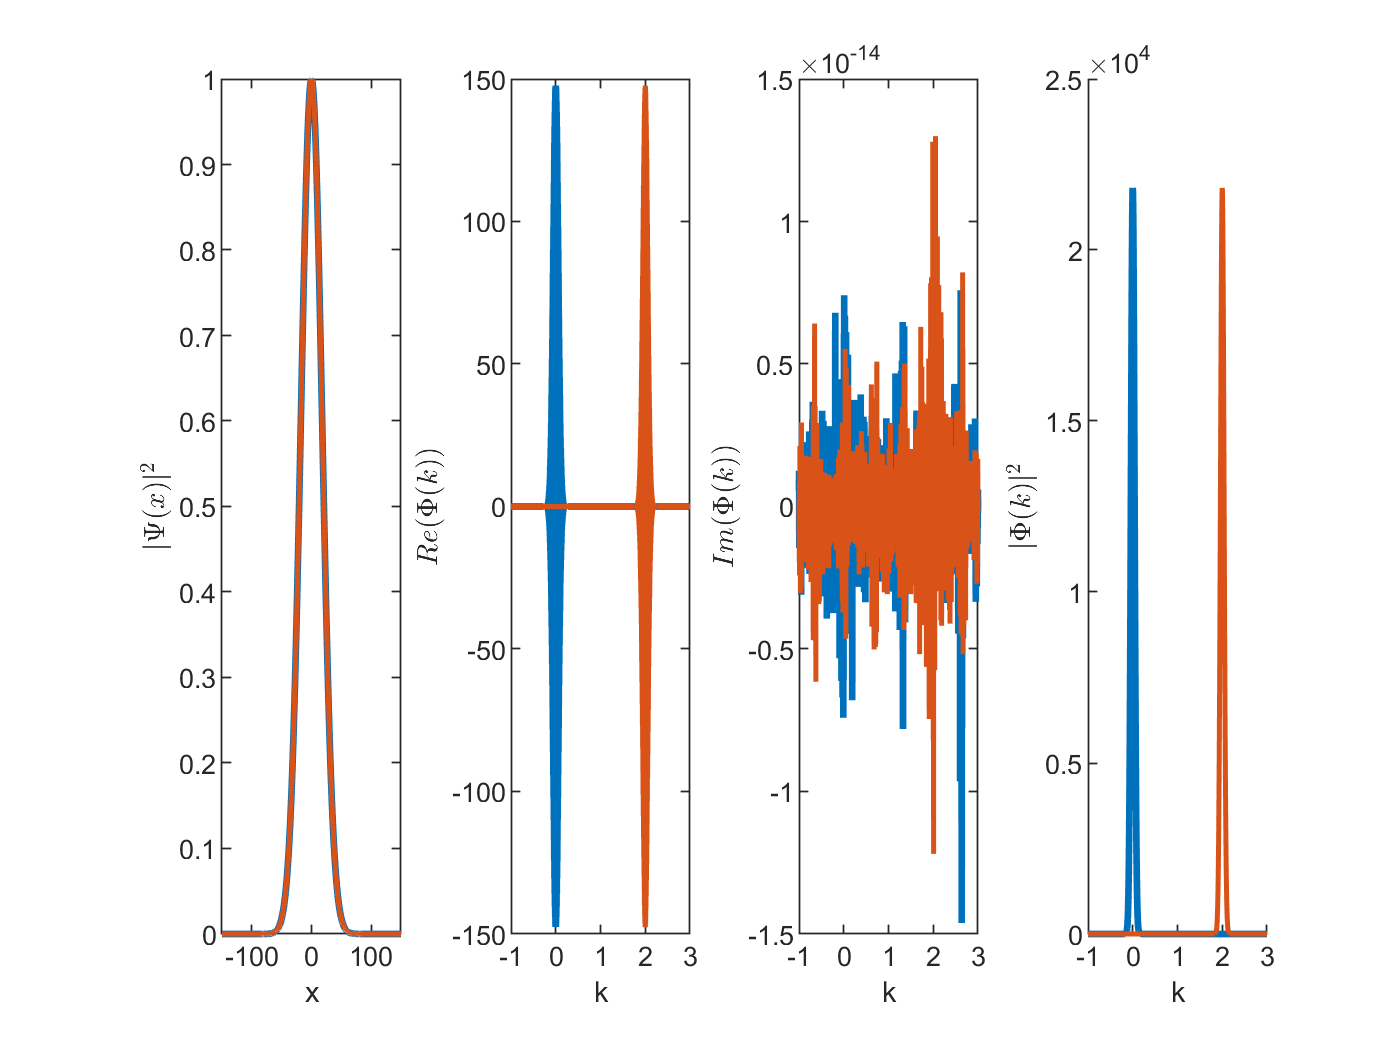

%% Visualize test wavepackets
% Make wavepackets in position and momentum
test1 = exp(-x.^2/25^2);
test2 = exp(-x.^2/25^2).*exp(1i*2*x);
test1hat = fftshift(fft(test1));
test2hat = fftshift(fft(test2));

% Plot
subplot(141);
plot(x,abs(test1),'linewidth',2); hold on;
plot(x,abs(test2),'linewidth',1.5); xlim([-150 150]);
xlabel('x'); ylabel('$|\Psi(x)|^2$','interpreter','latex');
subplot(142);
plot(k,real(test1hat),'linewidth',2); hold on;
plot(k,real(test2hat),'linewidth',1.5); xlim([-1 3]);
xlabel('k'); ylabel('$Re(\Phi(k))$','interpreter','latex');
subplot(143);
plot(k,imag(test1hat),'linewidth',2); hold on;
plot(k,imag(test2hat),'linewidth',1.5); xlim([-1 3]);
xlabel('k'); ylabel('$Im(\Phi(k))$','interpreter','latex');
subplot(144);
xlabel('k'); ylabel('$|\Phi(k)|^2$','interpreter','latex'); hold on;
plot(k,abs(test1hat).^2,'linewidth',2);
plot(k,abs(test2hat).^2,'linewidth',1.5); xlim([-1 3]);

So everything works out appropriately. Now, for systems where the dynamics are perfectly symmetric, this is the ideal and proper way to set up the grid.

**Oftentimes however, you may only get dynamics on one half of the position grid, and so you may want an asymmetric grid.** In my experience, it seems fine to do this even though the grids are supposed to be zero-centered. From a physics perspective, I understand this as the freedom to shift my system's position coordinates (of the potentials and initial state); from a technical perspective, this basically introduces an overall phase when computing the momentum space wavefunction (Fourier transform shift theorem), which is lost upon taking the inverse FFT back to position or when computing $|\Psi|^2$. Let's see this previous example on an asymmetric position grid, where I now like to define $x_0$ and $x_{N-1}$ rather than $h$:

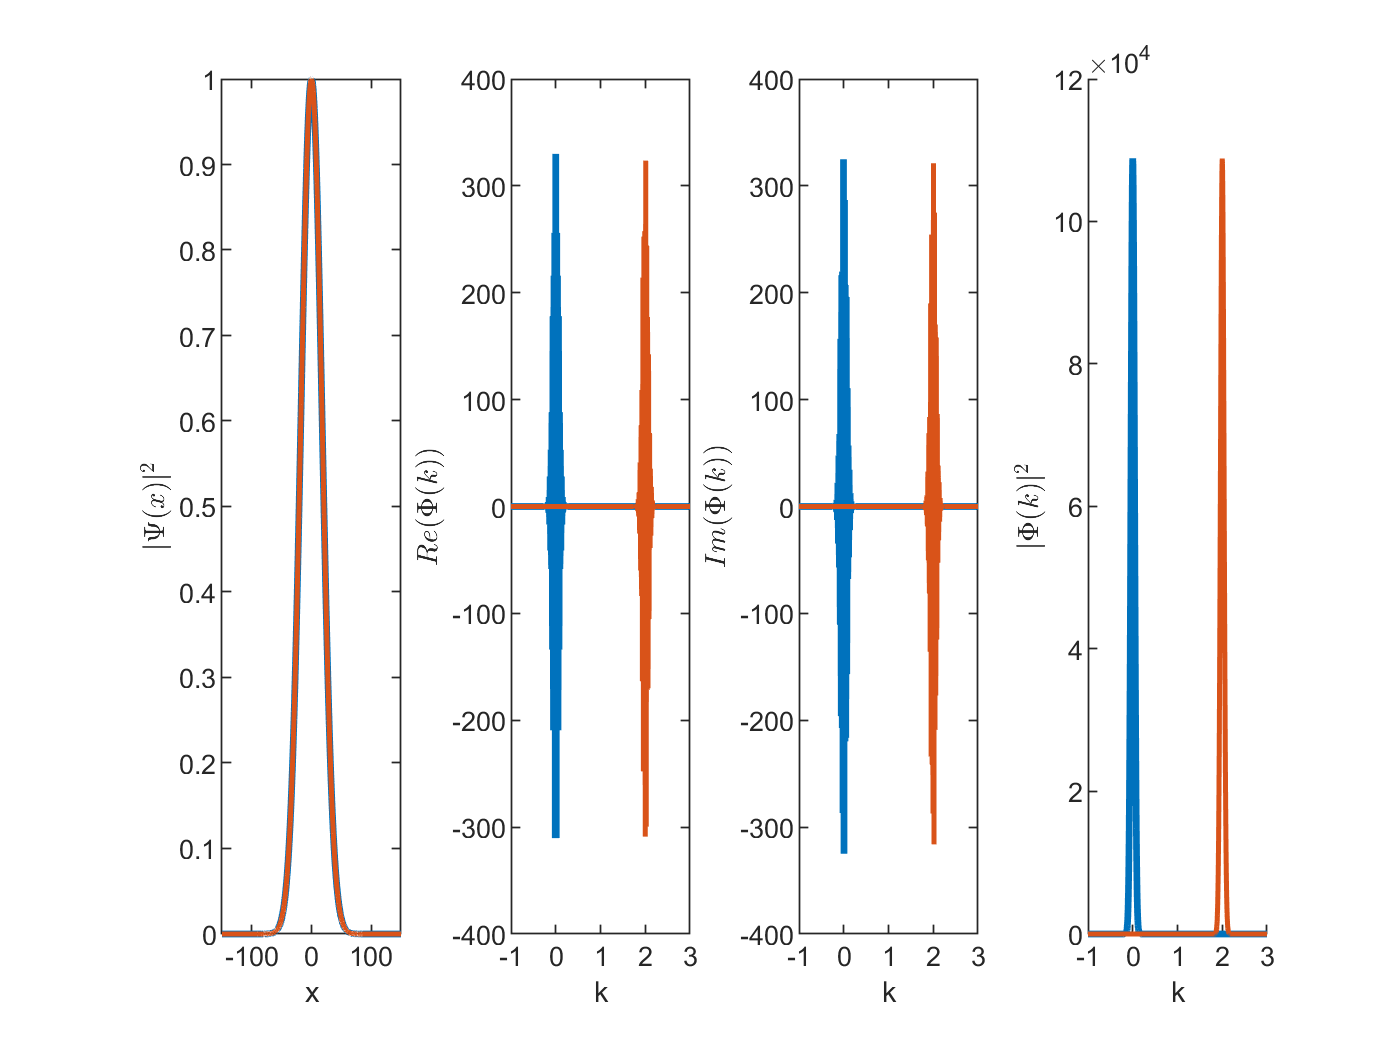

%% Define Position-Momentum Mesh
xmin = -300; xmax = 800;          % Position bounds
N = 2^13;                         % Number of points
x = linspace(xmin,xmax,N);        % Position Mesh
h = (xmax-xmin)/(N-1);            % Position Mesh Spacing
h2 = 2*pi/h/(N-1);                % K Mesh spacing in kL
k = h2*(-N/2:1:N/2-1);            % Momentum Mesh

%% Visualize test wavepackets
% Make wavepackets in position and momentum
test1 = exp(-x.^2/25^2);
test2 = exp(-x.^2/25^2).*exp(1i*2*x);
test1hat = fftshift(fft(test1));
test2hat = fftshift(fft(test2));

% Plot
f1 = figure(1); clf;
subplot(141);
plot(x,abs(test1),'linewidth',2); hold on;
plot(x,abs(test2),'linewidth',1.5); xlim([-150 150]);
xlabel('x'); ylabel('$|\Psi(x)|^2$','interpreter','latex');
subplot(142);
plot(k,real(test1hat),'linewidth',2); hold on;
plot(k,real(test2hat),'linewidth',1.5); xlim([-1 3]);
xlabel('k'); ylabel('$Re(\Phi(k))$','interpreter','latex');
subplot(143);
plot(k,imag(test1hat),'linewidth',2); hold on;
plot(k,imag(test2hat),'linewidth',1.5); xlim([-1 3])
xlabel('k'); ylabel('$Im(\Phi(k))$','interpreter','latex');
subplot(144);
xlabel('k'); ylabel('$|\Phi(k)|^2$','interpreter','latex'); hold on;
plot(k,abs(test1hat).^2,'linewidth',2);
plot(k,abs(test2hat).^2,'linewidth',1.5); xlim([-1 3]);

Indeed, we see that the momentum wavefunction after FFT has changed (signficiant imaginary part), but the resulting distribution remains the same (up to normalization since the grid size is slightly different). This is by no means a proof, but I have not yet observed issues with asymmetric grids yielding poor results.

Can you make both grids asymmetric? Generally I think no, though perhaps if you're careful about it you can get away with it. For instance let's consider a plane wave $e^{ikx}$ initially defined on our position grid. If you choose to shift the momentum grid, it will obviously evolve as the $k+k_{\text{shift}}$ state rather than just the $k$ state which is obviously a problem. What if you define the initial state on the momentum grid instead? Well in this case it might be possible. Those two perspectives on what enabled the freedom from earlier appear actually to be separate freedoms. The phase shift of the Fourier transform allows for me to make the momentum grid asymmetric, and the freedom to shift where the potential is in space would allow me to make the position grid asymmetric. My final word on this is just to be careful; these tricks will be of varying degrees of usefulness and one has to be diligent to make sure the right physics ends up captured.

**What if we have a 2D or 3D system?** For this method, you can do the exact same thing. Create your $x, k_x$ mesh, then create a $y,k_y$ mesh, and that's about it. You'll want to define the positions all over a single 2D matrix, but that's trivial using Matlab's meshgrid function. Note, that while simple in implementation, higher dimensions will scale poorly in computation time, though this is generically true of all methods. Here's an example of a 2D grid:

Before moving onto the time-splitting aspect of TSSP, let's recap on why we want to express our wavefunction in both bases. Namely, the challenge in time evolution is that $H$depends on momentum, and so $H$ and subsequently the time evolution will not be diagonal in the position basis. Put in pure PDE solving terms,** it's not trivial how to represent spatial derivatives which are not spatially local over a finite grid of points in space**. In the next section, we'll see how spectral decomposition along with time-splitting deals with this by exploiting transformations back and forth between position and momentum. I will mention in passing another very common class of method of spatial discretization known as **Finite Difference**. This essence of this is that it's based on the discrete approximation for the second derivative taught in introductory calculus:


$$\frac{\partial^2 }{\partial x^2 }f\approx \;\frac{f_{j+1} -2f_j +f_{j-1} }{h^2 }\ldotp$$


Thus, you'll write your second derivative as a tridiagonal matrix where each position is coupled to it's two nearest neighbors. The advantage of this is that it allows you to perform the integration in a single basis, but it's not diagonal which is something we'll see will become available in the TSSP once we consider the time discretization.

## Time Splitting - Discretizing Time

As I mentioned earlier there are two main questions to deal with, namely how to deal with both the time and space derivatives. **We answered the spatial derivative part,** **but at this point it should be completely not clear how it helps until we decide on how to deal with the time derivative** (i.e. if you go into the momentum basis, then you will have derivatives with respect to momentum corresponding to $V(x)$). Here, we'll now make it clear why **time splitting** works so well with spectral decomposition.

Recall that the generic solution for time evolution over an infinitesimally small interval $dt$ is to apply the operator $e^{-i H dt}$. If you can write down $H$ in matrix form, you could always ask Matlab to do this using expm; however this scales poorly (~$N^3$). Moreover, in our spectral method for the momentum operator we don't even know how to write this down. Thus we have to do something else.

The essence of **time-splitting** or **split-operator** methods is to employ approximations of the form


$$e^{\left(A+B\right)\mathrm{dt}} \approx e^{A\;\mathrm{dt}} e^{B\;\mathrm{dt}} ,$$


when solving equations of the form


$$\partial {\;}_t u=A\;u+B\;u\ldotp$$


In connection to our problem of the TDSE, we have that $A$is the operator representing the momentum portion of $H$, and $B$ is the operator representing the spatially local (position) portion of $H$, i.e. $V(x,t)$ and nonlinear mean field interactions. This means we can evolve using $e^{B dt}$ in the position basis, FFT into the momentum basis to apply $e^{A dt}$, and then FFT back to complete the time-step. In terms of the TDSE, this means we're splitting up the TDSE into two separate equations which we'll solve in alternating fashion:


$$\begin{array}{l}
i\;\frac{\partial }{\partial t}\Psi =\rho^2 \;\Psi ,\\
i\;\frac{\partial }{\partial t}\Psi =V\left(x,t\right)\;\Psi \ldotp 
\end{array}$$


Now it should be clear why we want two bases. Evolution of each of these equations is fairly trivial when you're in the momentum basis for the first and the position basis for the second. As long as we take small enough time steps, then switching back and forth between solving one equation and then the other will converge to actually solving both at the same time as in the exact solution, with some error in the time step that scales depending on how many splits we make.

To be explicit in how we're handling the time derivative: **we'll be integrating each time derivative equation exactly by applying a diagonal time evolution operator over small steps and transforming successively between the two bases**. In slightly more correct terms, we'll be integrating the second equation exactly in this manner, and then solving a wave equation with second order spatial derivative by a standard Fourier technique.

The path forward to implementing is this:

- **Set up a uniform time discretization.**

- **Compute the relevant diagonal operators in the Hamiltonian.**

- **Compute the propagators.**

**Step 1**. For system with no explicit time dependence, this is pretty trivial. Just set up a uniform time spacing from $t=0$ to $t=t_f$. In order to get convergence, the time step $dt$ will depend in particular on the effective Planck constant (normally multiplies the time derivative and is in the definition of the momentum operator); I find to get convergence for our undimensionalized $H$ (where effective Planck constant is 1) that $dt<0.1$. 

In this example, I go through a little extra trouble since I have a periodic function in time. Namely if the potential depends on time but is not periodic (or if there are interactions), you'll have to suffer with recreating the propagators at every step; for periodic potentials you can set your spacing so that you sample the same points in the waveform and can just reapply a finite number of premade operators. Once again, don't worry about these details but just know there are tricks sometimes.

Finally, generally you won't want to save the wavefunction at every step since there will often be 10$^5$-10$^6$ steps, so it's advised to set up a counter to determine when to save the wavefunction. Altogether the code to set up the time mesh could look something like (normally the first 2 lines will just be a single line like dt=0.1.):

%% Time Discretization
cycle = 25;                    % time steps per drive cycle
dt = 2*pi*omegar/omegaD/cycle; % time spacing in 1/omegaR
tf = omegar*TB;                % end time in 1/omegaR
tsteps = round(tf/dt);         % total number of time steps
saves = 100;                   % total number of times to save the wavefunction
savestep = tsteps/saves;       % how often to save
save = 1;                      % save counter

**Step 2**. Now we'll compute the relevant operators in the Hamiltonian. In fact, we already did the momentum operator; it's just our $k$ vector that we defined for our spectral grid. So all that's left is the potential operator. We just need to copy down our closed form for it that we undimensionalized already and evaluate it over the$x$ vector which we also have from the earlier spatial discretization. So we have:

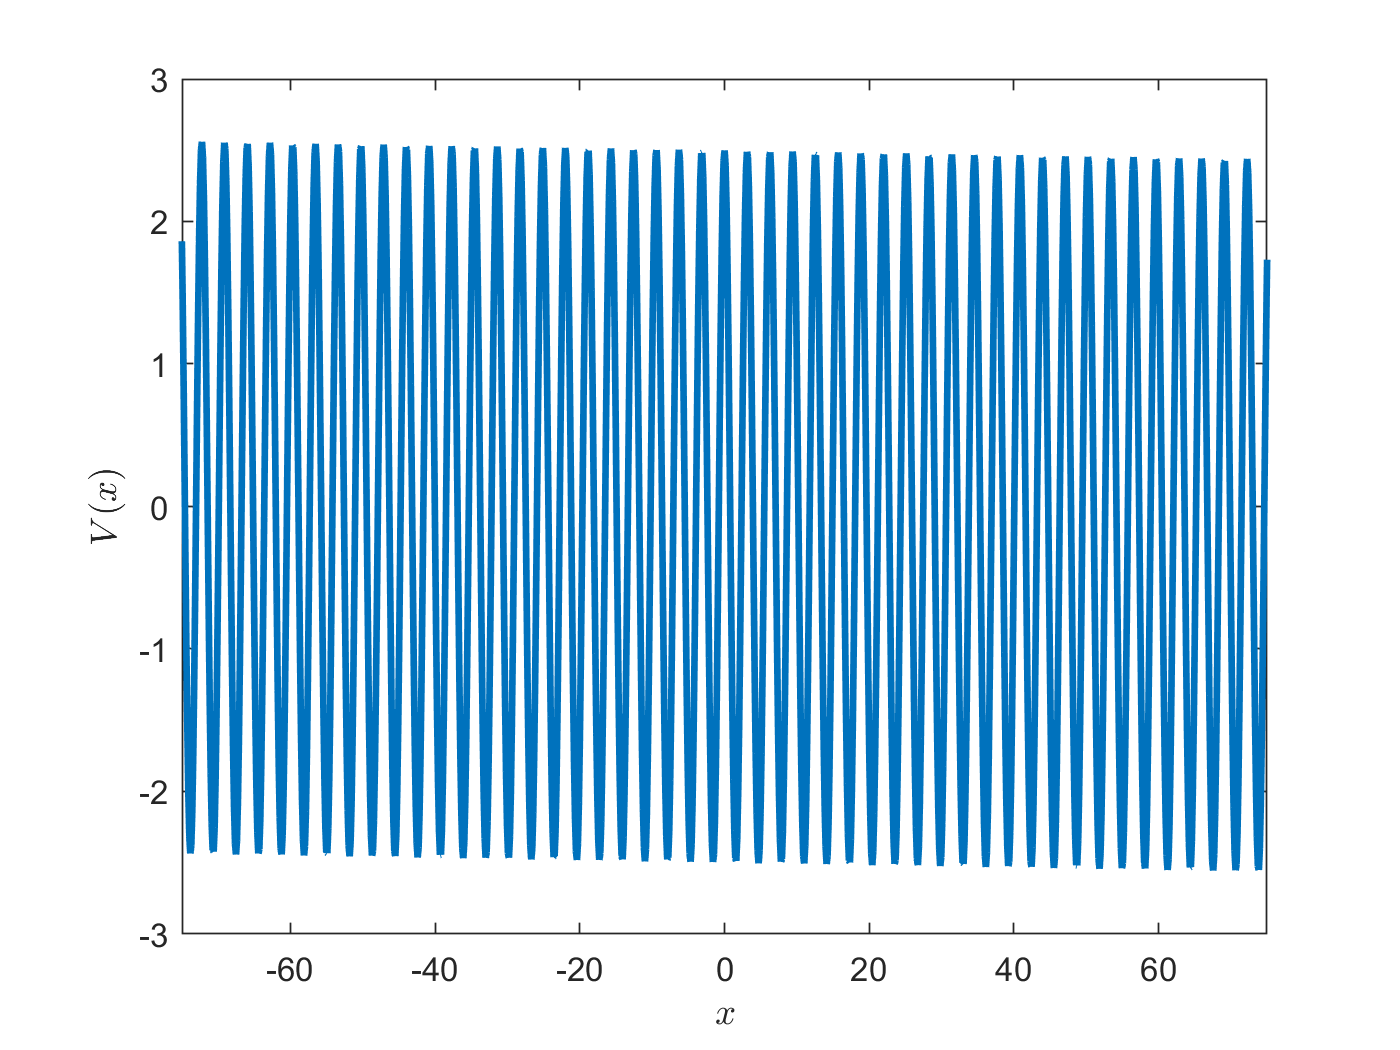

%% Potentials
VLat = (V0/2)*cos(2*x');
Vforce = (omega/omegar)^2*(x'/2).^2 - (omegaB/omegar)*(x'/pi);
Vmod = @(t) 1+alpha*sin(omegaD/omegar*t);

% check potentials
figure(2); clf;
plot(x,VLat*Vmod(0)+Vforce,'linewidth',2);
xlim([-75 75]);
xlabel('$x$','interpreter','latex'); ylabel('$V(x)$','interpreter','latex');

**Step 3**. Finally, let's compute the propagators. Remember, doing this here will only be applicable for the momentum and when the potential has nice time dependence; otherwise you'll construct it at each step in the integration loop.

First, let's be more explicit about their form. When I introduced time-splitting I explicitly wrote down the lowest order Lie splitting, which makes errors which are first order in the time step. However, the accuracy can be improved by breaking up each step into smaller splittings and more applications of the exponential operator. The most common is the so called symmetric Strang splitting given by

$e^{\left(A+B\right)\textrm{dt}} \approx e^{\frac{B\;\textrm{dt}}{2}} e^{A\;\textrm{dt}} e^{\frac{B\;\textrm{dt}}{2}}$.

This improves the method to second order errors in $dt$, and actually doesn't require any extra FFT operations, so the cost is only a single element wise multiplication. Here, the momentum part is$A = -i k^2$. If the potential doesn't have time depedence or interactions, we'll just have $B=-iV$. For this example though, $B$ represents the integral of the potential over the relevant time step, which we'll have to approximate. For time $t_n  = n dt$, we'll use Simpson's quadrature rule (unless it's a linear ramp in which case you can use trapezoidal rule which is exact) to get

$\int_{t_n }^{t_{n+\frac{1}{2}} } V\left(t\right)\mathrm{dt}\approx \frac{1}{6}\left(V\left(t_n \right)+4V\left(t_{n+\frac{1}{4}} \right)+V\left(t_{n+\frac{1}{2}} \right)\right)\frac{\mathrm{dt}}{2}=B\;\frac{\mathrm{dt}}{2}$.

For the second application of $B$, the integration should be taken from $t_{n+1/2}$ to $t_{n+1}$. I believe in order for this splitting to actually be second order, the integral approximation must also be second order.

Below, I construct these potential propagators over just a single drive cycle due to periodicity. In total, this gives:

%% Construct Propagators
UV = zeros(N,2*cycle);
for ii = 1:cycle
    V1 = (Vmod(dt*(ii-1)) + 4*Vmod(dt*(ii-3/4)) + Vmod(dt*(ii-1/2)))/6;
    V2 = (Vmod(dt*(ii-1/2)) + 4*Vmod(dt*(ii-1/4)) +  Vmod(dt*ii))/6;
    UV(:,2*ii-1) = exp(-1i*(V1*VLat+Vforce)*dt/2);
    UV(:,2*ii) = exp(-1i*(V2*VLat+Vforce)*dt/2);
end
Uk = exp(-1i*k'.^2*dt);

And with that, we've constructed all the necessary pieces to begin integrating. At this points, all that's left is to define the initial value of the wavefunction and then start applying these propagators.

For the rest of this section, I'll discuss a little bit about interactions. **For the case of interactions**, it unfortunately becomes necessary to recreate the $B$ part of the evolution at every time step, where the nonlinearity $|\Psi|^2$ is evaluated at the current time of the splitting ($t_n$ for the first half, $t_{n+1/2}$ for the second half). However, it's still just a single, easy line of code to write. If c is the current wavefunction, then every time you need to apply $e^{B dt/2}$ requires defining a new propagator that looks like:

I won't discuss how to get a numerical value for $g$ here. In general, it's not a simple procedure unless you're in 3D, but you can always just set it to a finite value to study the effects of the nonlinearity. A key point here is that it's no more challenging in practice to include interactions into the calculation for TSSP; in other discretization schemes this isn't always the case. However, it does require care to make sure the mesh (both space in time) are sampled finely enough to minimize numerical instability.

I said in an earlier section you could define your wavefunction on either position or momentum grid, i.e. implying that you can do this time evolution in either order. To be clear, I am not 100% aware of the consequences of switching the order of the time splitting (doing momentum evolution twice versus position); in the literature, it is always done in the manner presented above. I'll just say I believe it's technically fine to do this; if given a harmonic oscillator Hamiltonian, you probably wouldn't question this point at all. However, you have to be careful about stability. You should think about it like you're now integrating the momentum equation exactly and then solving a wave equation with potentially infinite order momentum derivatives (for instance our cosine lattice) using Fourier methods. I've observed that this does give a convergent solution in the case of the noninteracting kicked rotor. Interactions are where it gets a little hairy, since now you have a nonlinear, nonlocal term (in the momentum basis) in the Hamiltonian. I think in general, you can still proceed roughly in the manner above, but it might not be guaranteed that the Strang splitting is second order accuracy anymore. In practice, this should all be easy to test; set up the integrator both ways and check how they perform relative to each other at similar time steps.

## Setting an Initial State

The last thing we do before we write down the integration is to write down an initial wavefunction, since as mentioned at the beginning we are solving an initial value problem. The simplest thing you can do is define a Gaussian, which I did in the spatial discretization section and is easy to implement in any number of dimensions. However, this is not an eigenstate of a lattice and will thus be projected immediately into higher bands, which often is not the experimental protocol. A simple way to handle this is to simulate the ramp into the lattice, which is easy to implement but potentially costly in computational time.

Here, I'll take a little detour from our goal to explicitly show a simple method to prepare a 1D Bloch wavepacket which can be at any quasimomentum in any band (given that you the momentum mesh is large enough), which is common for BEC lattice experiments. By adding a for loop over quasimomentum, you can use the code block below to get the full band structure as well.

To prepare a Bloch wavepacket in the $n$th band centered at quasimomentum $q_0$, we utilize the fact that the lattice only couples states separated by 2$k_L$. The matrix elements in the momentum sub-basis are well-known and thus it is easy to diagonalize. Then we simply write down the expansion of the Bloch wavefuction in position space before multiplying by a Gaussian envelope:

%% Compute Initial Bloch Wavepacket
n = 1;                      % initial band
q0 = 0;                     % central quasimomentum
sx = 25;                    % BEC width
Nbands = 25;
q = -Nbands+1:2:Nbands-1;
% Matrix elements
Vmat = (V0/4)*gallery('tridiag',Nbands,1,2,1);
Tmat = sparse(1:Nbands,1:Nbands,(q0+q).^2,Nbands,Nbands);
% Compute Bloch states represented in the plane wave basis
[v,~] = eig(full(Vmat+Tmat));
vn = v(:,n);
% Compute Bloch function in position space
unk = @(x) 0;
for jj=1:Nbands
    unk = @(x) unk(x) + vn(jj)*exp(1i*(q(jj)+q0)*x);
end
% Initialize State vector
c = zeros(N,saves+1);     % matrix holding all state vectors
cii = unk(x').*exp(-x'.^2/(4*sx^2));   %Gaussian Bloch wavepacket
cii = cii/sqrt(cii'*cii*h);  % normalized wavefunction
c(:,1) = cii;

% Corresponding state in momentum space
fftconv = sqrt(h/(N*h2));    % normalization coversion factor
ciihat = fftconv*fftshift(fft(cii));

% Normalization check
disp(sum(abs(cii).^2*h));

    1.0000



disp(sum(abs(ciihat).^2*h2));

    1.0000



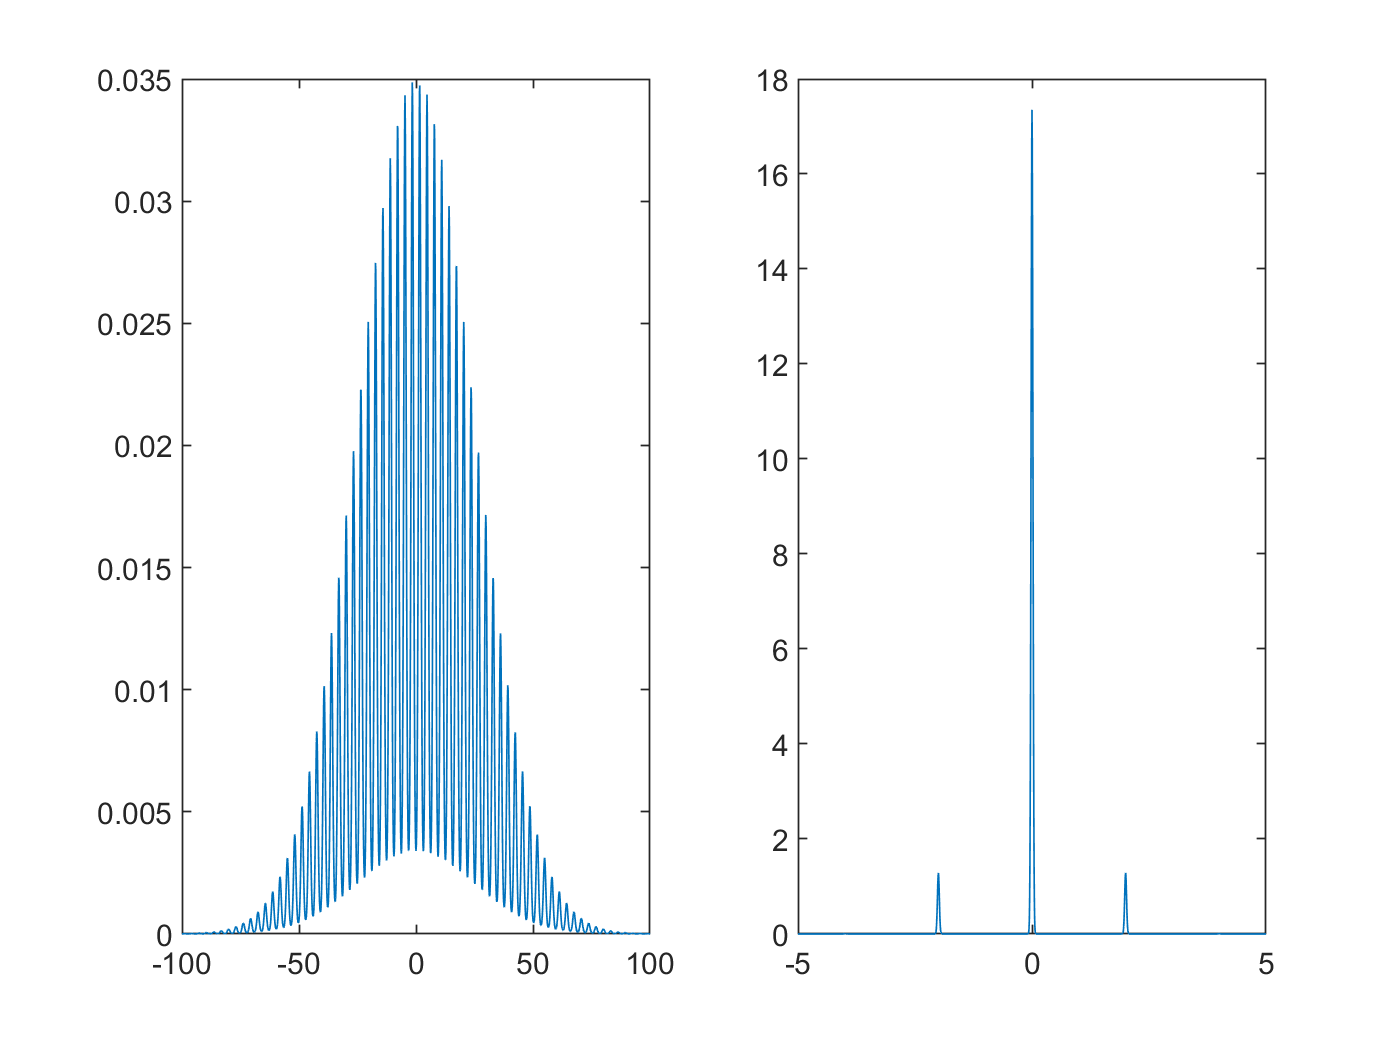


%plot
figure(3); clf;
subplot(121);
plot(x,abs(cii).^2); xlim([-100 100]);
subplot(122);
plot(k,abs(ciihat).^2); xlim([-5 5]);

Some points about normalization here at the end:

- For interacting systems, it is critical that the wavefunction be normalized so that its norm squared is a probability density and not a probability mass function. If not, unless the spacing $h = 1$, the solution will converge to the wrong answer.

- Here we use a simple Riemann sum, though trapezoidal integration is perhaps a cheap improvement. I've never observed a difference but worth keeping in mind.

- The dynamics are constructed to be unitary (mass-conserving), so it is not necessary to normalize at each time step. Of course if there are concerns about error accumulation, this can be done, though I'm not sure how this affects the solution. Usually, when I'll normalize when I save the wavefunction.

- It is not necessary to normalize the momentum wavefunction during the integration when the fft is performed since the inverse transformation back will always cancel it out anyway. However, if one wants to compute the moments of the momentum distribution, the momentum space wavefunction should be defined as it is above.

## Integrate

Finally, having methodically constructed all the necessary pieces, the implementation of the actual integration is very simple. Simply apply the operators we've constructed on the wavefunction and take FFT's back and forth between bases (there's a few extra characters in this code below to cycle through the preconstructed periodic potential operators, but the details aren't so important). It is shown here below:

for ii = 1:tsteps
    jj = mod(ii-1,cycle)+1;
    cii = UV(:,2*jj-1).*cii;
    cii = ifft(ifftshift(Uk.*fftshift(fft(cii))));
    cii = UV(:,2*jj).*cii;
    if ii/savestep > save
        save = save+1;
        c(:,save) = cii;
    end
end

## Check Results

Finally, let's briefly inspect our results. Here I'll just plot probability density.

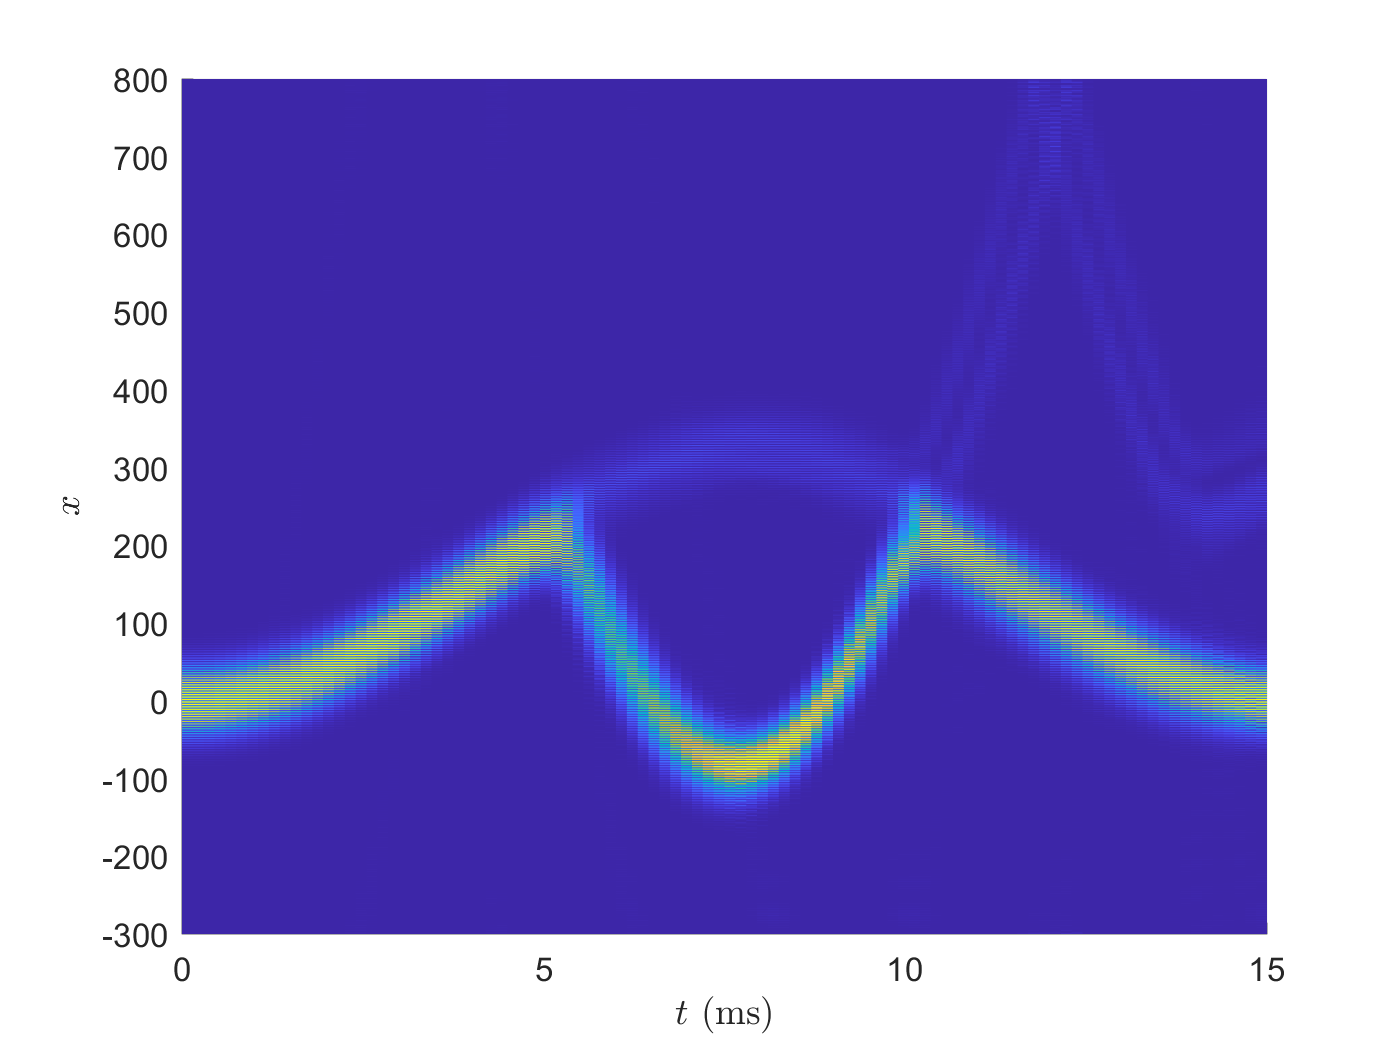

time = 0:dt/omegar*savestep:tf/omegar;
[T,X] = meshgrid(time,x);
figure(4);
surf(T*1E3,X,abs(c).^2);
ylim([min(x) max(x)]);
xlabel('$t$ (ms)','interpreter','latex'); ylabel('$x$','interpreter','latex');
caxis([0 .02]);
view(2);
shading flat;

So qualitatively, things look good; we get a Bloch oscillation at the period set in the code, as well as a transition to the first excited band due to the time periodic drive. If we were to look at the band structure, this would indeed coincide with what we expect. However, some important things to note:

- At about 12 ms, we see the packets in the p-band sharply reflect off the boundary of the grid. This is what generically happens when part of the wavefunction reaches the edge of your mesh (or it passes through to the other side), and is one of the most important errors to keep under control. Generally the wavefunction will have nonzero value everywhere on the grid, and thus there will constantly be reflections. The best way to control for these is to decide on a tolerance level and plot the wavefunction on a log scale to see at what level those reflections are feeding back into your wavefunction.

- Even if the behavior of the wavefunction seems qualitatively correct, that does not ensure convergence of the solution. To check this, I typically will plot the evolution of an observable (often the second spatial moment) for various values of $dt$. My experience is that getting the solution to converge at the level of accuracy dictated by the time splitting method demonstrates a sharp crossover in the behavior of these observables.

## TSSP vs other methods

At this point I haven't answered why use TSSP as compared to many other methods. Essentially, my thoughts on this are that this method is super simple, very transparent and extremely fast and easy to implement which is critical feature for experimentalists; most other methods involve solving systems of equations at each step, normally requiring the use of one of Matlab's magic solvers (not necessarily bad, just need to spend the time to learn what they are doing under the hood on a surface level) and are typically slower. There's sufficient literature on this topic in the context of the GPE which makes it clear that TSSP is one of the better methods in most cases, though of course there are always uses for others. In particular, TSSP with the Strang splitting is 2nd order in time and spectral (infinite) accuracy in space; it's easy to extend to fourth order in time, which mainly requires looking up some long coefficients that people figured out and doing more ffts. TSSP also features *time reversibility *(going backwards in time), *time transverse invariance *(you can shift the potential by a constant without changing anything), *mass conserving* (normalization conserved up to round-off error, I think of this as the fact that it's unitary), and has a *dispersion relation*. The only main property it fails on is in *conserving energy*.

If there is interest in other methods, they are basically all classified by their time and space discretization. Remember: **the problem of TDSE integration is just how to represent the derivatives of time and space. **Most of the simple methods use either spectral of finite difference spatial discretization. Other time discretizations include Crank-Nicolson, relaxation and semi-implicit. I'll briefly cover my simple understanding of Crank-Nicolson finite difference (CNFD) here for the noninteracting case.

As mentioned early, the essence of finite difference is approximating the second spatial derivative of the $p^2$ term as a tridiagonal matrix in the position basis where the elements are given by simple discrete approximation of the derivative. The Crank-Nicolson time discretization is understood as an averaging of the simple Euler method. The basic forward Euler method is:


$$\Psi_{n+1} \approx \left(1-i\;H\;\textrm{dt}\right)\Psi_n \ldotp$$


In other words, the first order approximation of the time evolution operator. There is also the backwards Euler method which is the same but you evolve the next time step back to the current one, which means the solution is given by inverting the matrix equation:


$$\left(1+i\;H\;\textrm{dt}\right)\Psi_{n+1} \approx \Psi_n \ldotp$$


To average these for Crank-Nicolson, you simply evolve each step to the halfway point:


$$\left(1+i\;H\;\frac{\textrm{dt}}{2}\right)\Psi_{n+1} \approx \left(1-i\;H\;\frac{\textrm{dt}}{2}\right)\Psi_n \ldotp$$


This means you apply a single matrix multiplication to do the half forward step, then invert the matrix on the left to complete the step. In pseudo-code this looks like

Here, the backslash is Matlab's standard matrix inverter. In 1D, this is really not so bad, since inversion of a tridiagonal matrix can be fast. However, generalizing to higher dimensions is a bit harder since things aren't diagonal and GPE papers often show that CNFD is not the best for interacting systems. On the other hand, TSSP is pretty simple in all dimensions since it's still just element-wise multiplication, just for higher dimension matrices, and as shown the interaction implementation is also easy.

## Concluding Remarks

After reading this, I think the fastest way to learn is just to try to implement a TSSP scheme from scratch once or twice (for instance try reproducing the result above). My experience is that after you set it up from scratch the first time, it feels very simple afterwards. If you take out all the superfluous commentary and extra plotting in the script, it's probably much less than 100 lines of serious code. I think its very feasible to crank these simulations out from scratch in 3-5 hours since its quite systematic and similar from one Hamiltonian to the next. This will be a huge benefit to feeding back with future experiments as well as exploring new ideas.